# 定義變數

GasPadelAxis=[0;0;1];                                               %踏板旋轉軸點
SensorAxis=[100;30;1];                                              %sensor 旋轉軸點
GasPadelForcePoint = [220*sind(-15); 220*cosd(-15); 1];             %腳踩在踏板上的點
GasPadelSensorPoint = [165.71*sind(-9.53); 165.71*cosd(-9.53); 1];  %sensor接在踏板上的點

PedalPushTheta=11.89*pi/180;        %踏板旋轉角
sensorLengthchange=[0,0,0];         %用來記錄等一下循環內需要的值，要初始化

## 計算機構變化

ind=1;  %計數器
for i=0:0.01:1 %用比例下去算目前轉了幾%，極限就是PedalPushTheta=11.89*pi/180
    
    %目前轉了幾度
    PedalPushThetaNow=PedalPushTheta*i;
    
    % 創建旋轉矩陣(踩踏板時踏板轉動的角度)
    GasPadelLocalation = [cos(PedalPushThetaNow) sin(PedalPushThetaNow) 0;
        -sin(PedalPushThetaNow) cos(PedalPushThetaNow) 0;
        0 0 1];
    
    %用旋轉矩陣去算出GasPadelForcePoint旋轉時會跑去哪
    GasPadelForcePointNow = GasPadelLocalation * GasPadelForcePoint;
    
    %用旋轉矩陣去算出GasPadelSensorPoint旋轉時會跑去哪
    GasPadelSensorPointNow = GasPadelLocalation * GasPadelSensorPoint;
    
    %求當下sensor的長度
    Sensorlength = sqrt((SensorAxis(1) - GasPadelSensorPointNow(1))^2 + (SensorAxis(2) - GasPadelSensorPointNow(2))^2);
    
    sensorLengthchange(ind,1)=PedalPushThetaNow*180/pi;         %紀錄轉角
    sensorLengthchange(ind,2)=Sensorlength;                     %紀錄sensor長
    sensorLengthchange(ind,3)=GasPadelForcePointNow(1);         %紀錄施力點x軸的移動量
    
    GasPadelSensorPoint_x(ind,1)=GasPadelSensorPointNow(1);     %紀錄施力點x軸的移動量
    GasPadelSensorPoint_y(ind,1)=GasPadelSensorPointNow(2);     %紀錄施力點x軸的移動量
    
    GasPadelForcePoint_x(ind,1)=GasPadelForcePointNow(1);       %紀錄腳踩在踏板上的點x值
    GasPadelForcePoint_y(ind,1)=GasPadelForcePointNow(2);       %紀錄腳踩在踏板上的點y值
    ind=ind+1;  %更新計數器
end

## 計算在不同轉角下sensor的變化

caulsensorLengthchange=[sensorLengthchange(1,2);sensorLengthchange(:,2)];   %開頭重複一次因應下面的for循環
for i=1:length(caulsensorLengthchange)-1
    a=caulsensorLengthchange(i)-caulsensorLengthchange(i+1);
    deltasensorLengthchange(i,:)=a;     %這個就是不同轉角下sensor壓縮的變化量
end
deltasensorLengt=sensorLengthchange(1,2)-sensorLengthchange(end,2);

## 畫圖

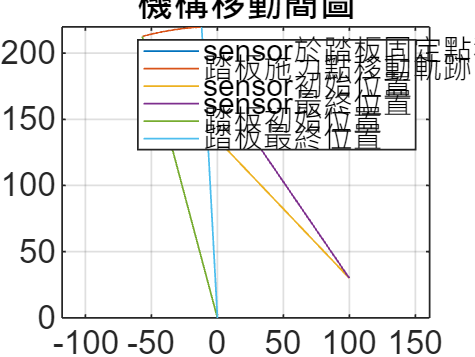

figure
plot(GasPadelSensorPoint_x,GasPadelSensorPoint_y)
hold on
plot(GasPadelForcePoint_x,GasPadelForcePoint_y)

plot([GasPadelSensorPoint_x(1);SensorAxis(1)],[GasPadelSensorPoint_y(1);SensorAxis(2)])
plot([GasPadelSensorPoint_x(end);SensorAxis(1)],[GasPadelSensorPoint_y(end);SensorAxis(2)])

plot([GasPadelForcePoint_x(1);GasPadelAxis(1)],[GasPadelForcePoint_y(1);GasPadelAxis(2)])
plot([GasPadelForcePoint_x(end);GasPadelAxis(1)],[GasPadelForcePoint_y(end);GasPadelAxis(2)])

title('機構移動簡圖')
legend('sensor於踏板固定點移動軌跡','踏板施力點移動軌跡','sensor初始位置','sensor最終位置','踏板初始位置','踏板最終位置',Location='northeast')
axis equal
grid on

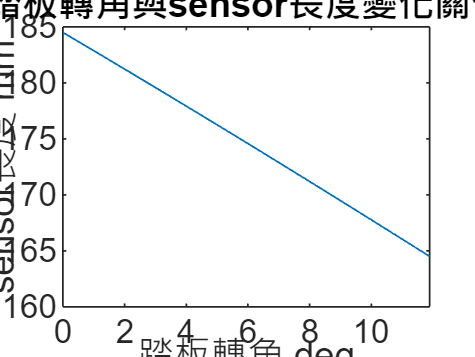



figure
%轉角對上sensor長度變化
plot(sensorLengthchange(:,1),sensorLengthchange(:,2))
title('踏板轉角與sensor長度變化關係')
xlabel('踏板轉角 deg')
ylabel('sensor長度 mm')

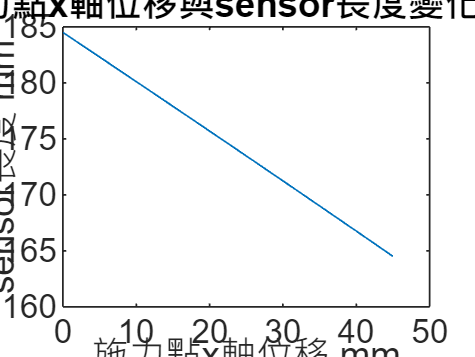


figure
%施力點x軸位移對上sensor長度變化
plot(sensorLengthchange(:,3)-sensorLengthchange(1,3),sensorLengthchange(:,2))
title('施力點x軸位移與sensor長度變化關係')
xlabel('施力點x軸位移 mm')
ylabel('sensor長度 mm')

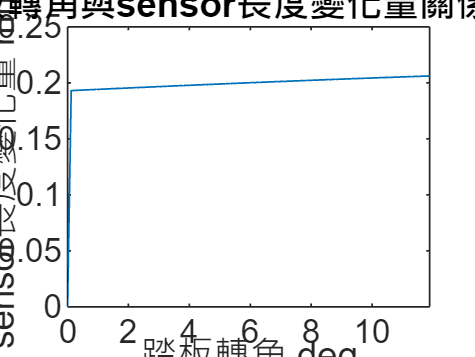


figure
%轉角對上sensor長度變化量
plot(sensorLengthchange(:,1),deltasensorLengthchange(:,1))
title('踏板轉角與sensor長度變化量關係關係')
xlabel('踏板轉角 deg')
ylabel('sensor長度變化量 mm')

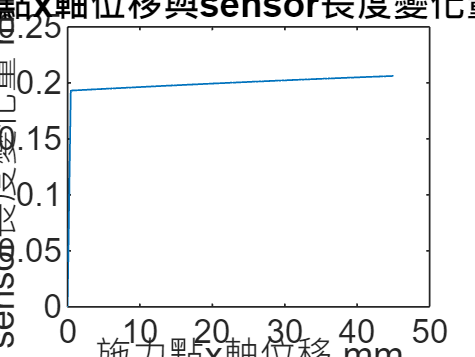


figure
%施力點x軸位移對上sensor長度變化量
plot(sensorLengthchange(:,3)-sensorLengthchange(1,3),deltasensorLengthchange(:,1))
title('施力點x軸位移與sensor長度變化量關係')
xlabel('施力點x軸位移 mm')
ylabel('sensor長度變化量 mm')